# **AERO21111 Space Systems **

## Introduction

This LiveScript covers the response to MATLAB tutorial 1 as required for the AERO21111 Space Systems module. During the course of this document I will analyse the overall performance characteristics for propulstion systems across a range of performance values in terms of the achievable change of velocity and fuel requirements. This broad analysis will then be used to solve a specific challenge in relation to the launch mass of the NASA/ESA Sentinal-6B spacecraft. The final step will then be to consider the results of this analysis in conjunciton with broader data on launcher performance across multiple areas to identify the most suitable vehicle to place the spacecraft into orbit.

# Propulsion Sensitivity and Mission Analysis

### Task 1 - Identify the Appropriate Equation

The total change in velocity$\Delta v$ requirements for a manoeuvre can be given as described in equation 5.31 of the course notes and shown below:

####             
$$\Delta v = \Delta v_{ideal} - \Delta v_D - \Delta v_g$$
 

Assuming that as the required manoeuvre is for a spacecraft already in orbit then there is no atmospheric drag loss $\Delta v_D$, and the loss due to gravitation $\Delta v_g$ is negligible as stated in the tutorial then: 

####              
$$\Delta v_D = \Delta v_g = 0$$
 

And so by extracting the relationship shown in equation 5.30 of the course notes it can be stated that the total change in velocity required for the Sentinal-6B orbital manoeuvre is given by:

####              
$$\Delta v = \Delta v_{ideal} = I_{sp}g \ln \frac{m_0}{m_1}$$


The constants and variables in this equation are:

- The specific impulse range:

####                 
$$I_{sp} = 200s - 300 s$$


- The range of required veloctiy changes:

####                 
$$\Delta v=1-2\;\textrm{km}/s$$


- The acceleration due to the Earth's gravity is 

####                 
$$g = 9.81\ m\ s^{-2}$$


- The initial mass of the spacecraft prior to the manoeuvre $m_o$ which can be given in terms of the dry mass $m_{dry}$ and the fuel mass $m_{fuel}$.

####                 
$$m_{0} = m_{dry} + m_{fuel}$$


- And the final mass of the spacecraft after the completion of the manoeuvre $m_{1}$ assuming that all fuel is expended is given soley by the dry mass as defined in the tutorial:

####                 
$$m_1 = m_{dry} = 1000\ kg$$


Inserting these values into equation 5.30 and rearranging to make $m_{fuel}$ the subject gives:

####                 
$$m_{fuel} = m_{dry} \left( e^{\frac{\Delta v}{I_{sp}g}} - 1 \right)$$


### Task 2 - Establish the input values

Now that we have identified the correct equation the required input values can be defined in code. First we will create constants for the dry mass and acceleration due to gravity (in appropriate units):

mdry          = 1000;                             %[kg] Dry mass of the satellite
g             = 9.81*10^(-3);                     %[km/s^2]

The next step it to define an input range for the specific inpulse and Delta v that will allow a range of analysis. In this case I have chosen to create an array for the specific impulse between 200 - 300 seconds with steps of 1 second, and for a change in velocity between 1 and 2 $km\ s^{-1}$ with steps of 0.01 $km\ s^{-1}$ as follows:

Isp           = linspace(200,300,101);            %[s] Specific impulse (100 increments)
DeltaV        = linspace(1,2,101);                %[km/s] Required velocity change (100 increments)

### Task 3 - Create the 2D Mesh

The 2D mesh can be created by applying the **meshgrid** command and using the vectors already defined for specific impulse and change in velocity. This will convert the vectors into equally sized arrays that are suitable for comparison and further analysis.

[ISP,DV]     = meshgrid(Isp,DeltaV);            % Creates an equally sized array for the ISP and velocity change ranges.

### Task 4 - Calculating the Required Fuel Mass

Now that we have the required input values we can use the equation already defined in task 1 to identify the required fuel mass across our range of specific impulses and velocity changes as follows:

mfuel         = mdry.*(exp(DV./(g.*ISP))-1);      %Calculating the fuel mass required in kg for a range of ISP and velocity changes.

### Task 5 - Generating the Surface Plot

To conduct the sensitivity analysis for the mass of fuel required in relation to a defined specific impulse and velocity change we can use the output of previous tasks to create a surface plot as follows:

surf(ISP,DV,mfuel)                                % Create a surface plot in terms of ISP, change in velocity and fuel mass
view(0,90)                                        % Display the plot in 2D

The final step in generating the plot is to ensure that it is clear and readable, with appropriate labels and a key to allow identification of output values

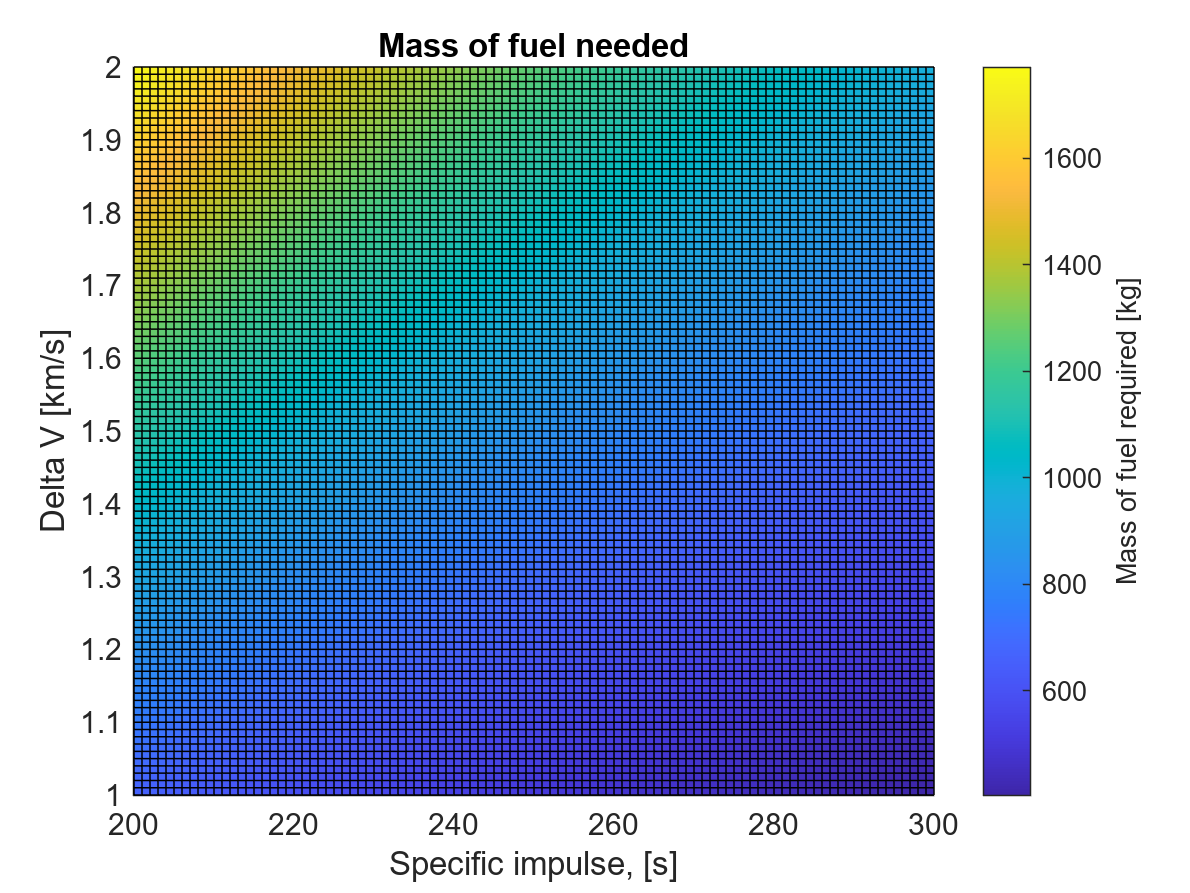

xlabel('Specific impulse, [s]')                   % Adds the required label to the x axis
ylabel('Delta V [km/s]')                          % Adds the required label to the y axis
title('Mass of fuel needed')                      % Adds an appropriate title
colorbar                                          % Generates a colorbar to the side of the surface plot
ylabel(colorbar, 'Mass of fuel required [kg]')    % Labels the colorbar in the vertical direction

If the LiveScript is now run up to this point a surface plot is generated showing the mass of fuel required in $kg$ against a specific impulse from 200 - 300 seconds and a velocity change between 1 and 2 $km\ s^{-1}$. A system engineer can use this plot and the peformance capability of the spacecraft engine to identify the fuel mass required to complete a manoeuvre involving a specific change in velocity.

### Task 6 - Identifying the Total Launch Mass

The tutorial question states that the planned manoeuvre for Sentinal-6B will require a change in velocity of $\Delta v = 1.3\ km \ s^{-1}$ and that the spacecraft thruster has a specific impulse of $I_{sp} = 230\ s$. Using the surface plot created in task 4 the required fuel mass in kg to perform the manoeuvre is: 

####                 
$$m_{fuel} = 779.201\ kg$$


The assumed spacecraft dry mass as given in the tutorial is:

####                 
$$m_{dry} = 1000\ kg$$


And so the total launch mass of the spacecraft required to perform the stated orbital manoeuvre can be estimated as: 

####                 
$$m_{total} = m_{dry} + m_{fuel} = 1779.201\ kg$$


Given that this is an early stage calculation I will add a fuel margin of approximately 10% and thus approximate the total mass as :

####                 
$$m_{\textrm{total}} =1850\textrm{kg}$$


### Task 7 - Selecting a Launch Vehicle

**Mass Requirements**. 

Table 1 in the tutorial shows that all the launch vehicles can place the required total mass into a polar orbit and so all are potential options at this point.

**Reliability Assessment**. 

Using the values provides the launch reliability of each vehicle has been calculated as follows:

    -    Falcon 9 $\approx 98.4\%$

    -    Ariane 5 $\approx 95.4 \%$

    -    Atlas V $\approx 98.9\%$

    -    Delta IV Medium $\approx 94.9\%$

As the Delta IV has a reliability below $95\%$, albeit on a much lower number of flights and accounting for the fact that most failiures happen early in a vehicles operational lifespan, I have chosen to discount that as an option at this point.

**Environmental Impact**. 

Based on the provided emissions values the remaining launch vehciles have been ranked in accordance with their oupt from low to high:

    -    CO2 emissions: 

                 1. Ariane 5

                 2. Atlas V 

                 3. Falcon 9

    -   H2O emissions:

                1. Ariane 5

                2. Atlas 5

                3. Falcon 9

And so it is clear that the Ariane 5 is the least polluting of the remaining launchers.

**Launch Site Selection**. 

The required orbital inclination of $66^0$ is achievable from all launch sites, however as it is in a prograde orbit this will likely require the initial direction of travel to be to the North East from the launch site to minimise launcher fuel expendature. This reduces the avaiable sites to:

    -    Kennedy Space Centre (CCAFS)

    -    Guiana Space Centre (FRGUI)

    -    Baikonur Cosmodrome (TYMSC)

The remaining launch vehicle options are operated by different states and so this limits the launch options as follows:

    -    Ariane 5: Guiana Space Centre (ESA)

    -    Atlas V: Kennedy Space Centre (United States)

    -    Falcon 9: Kennedy Space Centre (United States)

None of these vehicles are operated by the Russian Federation and so Baiknour Cosmodrome is discounted at this point.

A launch vehicle receives a boost from the Earth's rotation that increases in relation to the equatorial proximity of the launch site. In this case Guiana is the closest to the equator and so would receive the largest boost, although Kennedy would also receive some benefit to a lower factor.

**Final Launch Vehicle Selection**

Although the Falcon 9 and Atlas V both attain a greater reliability score than Ariane 5, this latter vehicle comes out on top in the analysis of environmental impact and launch site selection. Therefore the ESA Ariane 5 operating from Guiana Space Centre has been chosen as the preferred launch vehicle for the Sentinal-6B spacecraft based on these criteron.

### Summary and Conclusion

This LiveScript has covered the completion of tutorial 1 as part of the AERO21111 Space Systems MATLAB coursework. During the course of this assignment I have identified the required mathematical relationship between engine performance and fuel requirements based on a range of velocity changes. Using this relationship I have conducted a sensitivity analysis to provide a broad analysis and then applied it to assist in the solution of a specified problem. This was to find the fuel requirements for the Sentinal-6B spacecraft with a dry mass of 1000 kg able to perform a single velocity change of 1.3 $km\ s^{-1}$ using a thruster with an $I_{sp} = 230s$. This resulted in total launch mass of $\approx 1850\textrm{kg}$. Finally by combining the launch mass requirements along with the available launcher reliability, environmental impacts and launch site characteristics a judgement has been made as to the preferred launch provider. The result is that the preferred vehicle to launch Sentinal-6B into a prograde orbit at 66deg with minimal environmental impact is achieved by requesting the services of the ESA Ariane 5 capability operating out of Guiana Space Centre.

### References

Smith, K., and Macario-Rojas, A., 2023, 'Chapter 5: Propulsion & Launch Systems', *AERO21111 Space Systems Course Notes*, School of Engineering, The University of Manchester.

# Thermal Design

### Introduction

This LiveScript covers the response to MATLAB tutorial 2 as required for the AERO21111 Space Systems module. During the course of this document I will analyse the temperature changes over the course of the satellites orbital period as it goes in and out of eclipse. This broad analysis will then be used to determine wether the satellite will survive with out any addition thermal systems and suggest wether materials should be changed or heater should be added.

### Task 1: Defining Constants

In order to use equations we have to define our input values in our code first, this includes the Thermo-physical Data and the necessary parameters of our spacecraft.

Firstly the Thermo-Physical Data:

clear
q_s         = 1400;          %[W/m^2] Solar Radiation Flux
q_e         = 240;           %[W/m^2] Earth Radiation Flux
a_r         = 0.3;           %[] Earth Albedo
SB_Const    = 5.67*10^(-8);  %[W/m^2*K^4] Stephan-Boltzmann constant 
R_e         = 6371*10^3;     %[m] Radius of Earth
mu          = 3.986*10^14;   %[m^3/s^2] Standard Gravitational Parameter

Secondly the rest of the necessary parameters:

h           = 1336*10^3;     %[m] Altitude 
abso        = 0.46;          %[] Absorptance
emit        = 0.77;          %[] Emmitance
P_sun       = 1000;          %[W] Power Dissipated by Spacecraft in Sunlight 
P_ecl       = 500;           %[W] Power Dissipated by Spacecraft in Eclipse
A_surf      = 3.35;          %[m^2] Surface Area of Single Face
c_p         = 900;           %[J/kgK] Specific Heat Capacity
t_i         = -10+273.15;    %[K] Inital Temprature

**Discussion Task:**

We want to add a heater to keep our satellite in its operating temperature range. The tutorial sheet tell us that the mass of the heater is 5kg. The value of the power of the heater is 30W.

m_Heater    = 5;              %[kg] Mass of Heater 
P_Heater   = 30;              %[W] Power of Heater

The total mass will be the mass of the Satellite plus the mass of the heater.

m_total     = 1000  + m_Heater;          %[kg] Mass

The surface area of the Total Spacecraft is also a necessary parameter but has to be calculated from the Surface Area of a single face. From the course notes we can assume that:

## 
$$A_{\textrm{total}} =2A_{\frac{s}{c}}^S$$


Where $2A_{\frac{s}{c}}^S$is the surface area of single face and so we can calculate that:

A_total     = 6*A_surf;     %[m^2] Surface Area of Full Spacecraft

### Task 2.1: Calculating Thermal Time Constant

The first of which is the thermal time constant ( τt). To find the thermal time constant we can use Equation 6.45 in the course notes which is shown below:

## 
$$\tau_t =\frac{mc_p }{\varepsilon \sigma A}$$


where $m$ is the mass of the spacecraft, $c_p$ is the specific heat capacity, $\varepsilon$ is the emittance, $\sigma$ is the Stephan-Boltzmann constant and $A$ is the Surface Area of full spacecraft.

T_time_constant     = (m_total*c_p)/(emit*SB_Const*A_total);        %[] Thermal Time Constant

### Task 2.2: Calculating the eclipse duration for the satellite

In order to find the eclipse duration we need to first calculate the first orbit period, the orbit is cirular so the semi major-axis is the sum of the radius and altitude. We are assuming that the that the sun line is normal to surface.

From Equation 3.16 in the course notes we see that the equation to calculate orbital period is:

## 
$$\tau =2\pi \;\sqrt{\;\frac{a^3 }{\mu }}$$
 

- $\tau \;$is the orbital perod of a closed orbit in seconds

- $a$ is the semi-major axis; in this case it is the sum of the radius of the earth and the altitude 

- $\mu \;$is the gravitaitional parameter 

orbital_period_TH= (2*pi*(sqrt(((R_e+h)^3)/mu)));                  %[s] Orbital Period

Once the orbital period has been found we can find the that angles at whcih the satellite will be in eclipse, we have to make the assumption that the sun line is normal to the surface which will allow us to use the Equation 1 in the tutorial sheet:

## 
$$\theta =\arcsin \left(\frac{R_e }{R_e +h}\right)$$


- $\theta \;$are the angles at which the satellite is in eclipse in radians 

- $\textrm{Re}$ is the Radius of the Earth

- $h$ is the alitiude of the satellite in orbit

theta_eclipse       = asin(R_e/(R_e+h));                            %[rad] Angles at which the satellite is in eclipse in radians   

Now that we have the angle at which the satellite in in eclipse we can find the distance it travel while it is in eclipse by using the equation for arc length:

## 
$$S=r\theta \;$$


- $S$ is the arc length or in this case the distance that the satellite covers while in eclipse

- $r$ is the radius of the orbit which is the radius of the Earth and the altitude of orbit

- $\theta \;$is the angle at which the satellite is in eclipse in radians 

Then taking the result of this equation, which is the distance that is covered by the satellite covers while in eclipse we can calculate what fraction of the whole orbit the satellite travels in eclipse:

### 
$$\textrm{Eclipse}\;\textrm{Fraction}=\frac{S}{2\pi \left(R_e +h\right)}$$


- $\textrm{Eclipse}\;\textrm{Fraction}\;$is the fraction of orbit distance spent in eclipse

- $S$ is the distance the satellite travels in eclipse

- $R_{e\;}$is the radius of the earth 

- $h\;$is the altitiude of the orbit 

Using the eclipse fraction we can find the time spent in eclipse by multiplying it by the orbital period and in turn we can find the time spent in the sun by sfind the difference between the orbital time and the time in eclipse:

### 
$$\textrm{Eclipse}\;\textrm{Time}=\tau \cdot \textrm{Eclipse}\;\textrm{fraction}\;$$
    

- $\textrm{Eclipse}\;\textrm{Time}$ is the time spent in orbit

- $\tau \;$is the orbital period 

- $\textrm{Eclipse}\;\textrm{Fraction}\;$is the fraction of orbit distance spent in eclipse

### 
$$\textrm{Sun}\;\textrm{Time}=\tau -\textrm{Eclipse}\;\textrm{Time}$$


$\textrm{Sun}\;\textrm{Time}\;$is the time spent in the sun

$\textrm{Eclipse}\;\textrm{Time}$ is the time spent in orbit

$\tau \;$is the orbital period 

eclipse_distance    = theta_eclipse*(R_e+h);                        %[m] Distance covered in eclipse from Circle equations
eclipse_fraction    = eclipse_distance/(2*pi*(R_e+h));              %[] Fraction of Orbit travelled in eclipse 
eclipse_time        = orbital_period_TH * eclipse_fraction;            %[s] Time spent in Eclipses
sun_time            = orbital_period_TH - eclipse_time;                %[s] Time spent in the Sun 

### Task 4: Thermal Power Input and Equilibrum temprature

Our next task is to calculate the Thermal Power Input and use to calculate the Equilibrium Temprature. We need to do this twice, have one set of equations to calulate the equilibrium temprature during sun exposure and have another set of equations to calculate the equilibrium temprature during eclipse. 

To find the Thermal Power Input in the sun we can use the sum of all the heat input sources; Equation 6.37 in the course notes:

### 
$$Q_{\textrm{in}} =q_s \alpha_s A_{s/c}^S +a_r q_s \alpha_s F_{12} \;A_{s/c}^P \cos \phi \;\cos \theta_s +q_{\oplus } \varepsilon \;F_{12\;} A_{s/c}^P +P_{\textrm{dis}}$$


- $Q_{\textrm{in}}$ is the heat input 

The first term in this equation is the Direct Solar Radiation: $q_s \alpha_s A_{s/c}^S$

- $q_s$ is the solar radiation flux

- $\alpha_s$ is the absorbance of the material of the spaceship

- $A_{s/c}^S$ is the projected area of the spacecraft facing the Sun 

The second term in this equation is the Albdeo Radiation: $a_r q_s \alpha_s F_{12} \;A_{s/c}^P \cos \phi \;\cos \theta_s$

- $a_r$ is the Earth Albedo Radiation

- $q_s$ is the solar radiation flux

- $F_{12}$ is the view factor between the spacecraft and the planet

- $A_{s/c}^P$ is the projected area of the spacecraft facing the planet

- $\theta_s$is the angle the orbit plane makes with the Earth-Sun vector; in this case assumed to be zero since the sun line is normal to the surface

- $\phi$ is the angle as measured for a co-planar orbit

The third term in this equation is the Earth Shine: $q_{\oplus } \varepsilon \;F_{12\;} A_{s/c}^P$

- $q_{\oplus }$ is the Earth Shine; which is the thermal energy radiated by the planet 

- $\varepsilon \;$is the emissivity of the area of the spacecraft being considered

- $F_{12\;}$is the view factor between the spacecraft and the planet

- $A_{s/c}^P$ is the projected area of the spacecraft facing the planet

The final term in the equation is the On board Power dissipation denoted by $P_{\textrm{dis}}$ which takes different values depending on if the satellite is in eclipse or in the sun.

The Thermal Input Power in eclipse can be caluclated using the simplifed Equation 2 in the tutorial:

### 
$$Q_{\textrm{in}} =q_E A_E \varepsilon \;$$


- $Q_{\textrm{in}}$ is the heat input

- $q_E$is the Earth IR radaition

- $\varepsilon \;$is the emissivity of the area of the spacecraft being considered

Taking this Thermal Input Power we calculate the Equilibrium Temprature. The Equilibrium Temprature by the sun is given by equation 6.40 in the course notes:

### 
$$T_{\textrm{eq}} =\sqrt[4]{\frac{Q_{\textrm{in}} }{\varepsilon \sigma A_{\textrm{total}} }}$$


- $T_{\textrm{eq}}$is the Equilibrium Temprature

- $Q_{\textrm{in}}$is the Thermal Input Power

- $\varepsilon \;$is the emissivity of the area of the spacecraft being considered

- $A_{\textrm{total}}$is the total surface area of the satellite

R_R                = h/R_e;                                         %[] Radius Ratio
theta_sun          = 0;                                             %[] Since Sun vector is normal to the surface of the earth
F_12               = (cos(theta_sun)/(1+R_R)^2);                    %[] The View Factor between the spacecraft and the planet

Q_in_Sun           = (q_s*abso*A_surf)+(a_r*q_s*abso*F_12*(A_total-A_surf)*cos(theta_sun))+(q_e*emit*F_12*A_surf)-P_sun %[W] Qin (Thermal Input Power) in the Sun

Q_in_Sun = 3.7918e+03

Q_in_Eclipse       = (q_e*A_surf*emit) - P_ecl;                                                                          %[W] Qin (Thermal Input Power) in Eclipse     

T_eq_Sun           = nthroot(((Q_in_Sun)/(SB_Const*emit*A_total)),4)      %[K] Equilbrium Temprature of the satellite in the Sun      

T_eq_Sun = 256.3865

T_eq_Eclipse       = nthroot(((Q_in_Eclipse)/(SB_Const*emit*A_total)),4)  %[K] Equilbrium Temperature of the satellite in the Eclipse

T_eq_Eclipse = 107.9300

Discussion Task (Heater);

Q_in_Heater        = Q_in_Eclipse * P_Heater;                              %[W] Qin (Thermal Input Power) of Heater
T_eq_Heater        = nthroot((Q_in_Heater/(emit * SB_Const * A_total)),4)  %[W] Equilibrium Temprature of the Heater

T_eq_Heater = 252.5937

### Task 5: Change in Temprature over Time

In task 5 we calculate the change in temperature of the satellite over time, by setting P = orbital period*50 we can model the change in temperature over 50 orbits by interating it using a loop.

Below we initalise our variables by setting the values to zero or their inital values to ready them for iteration.

iterations         = 100;
P                  = orbital_period_TH*iterations;   %Total amount of Simulation Time
simulation_time    = 0;                  %Initialising Simulation Time
Time_elapsed       = [];                 %Created an array for time elapsed
orbit_counter      = 0;                  %Saves temperature to the values in the time array 
temp               = t_i;                %Initialising Temprature
temp_Heater        = t_i;                %Initialising Temprature
orbital_time       = 0;                  %Initialising Orbit time
dT                 = 0;                  %Initialising Change in Temprature


We then create a while loop that runs for the set number of orbits, until the simulation time reaches the end of 50 orbits. Time elapsed and temperature are added to arrays so that they can be used to see if the satellite is in eclipse or in the sun. Orbit Step Counter is used to assign a counter value for each change in temperature (dT) value, this means that that each temprature will have an assigned time to it. After checking these a new temprature is calulated before the interation restarts.

while simulation_time <= P
    orbit_counter                = orbit_counter + 1;
    Time_elapsed(orbit_counter)  = simulation_time;
    T_sat(orbit_counter)         = temp;
    T_sat_Heater(orbit_counter)  = temp_Heater; 

    if orbital_time < sun_time
        dT = (((T_eq_Sun^4)-((temp^4)))/T_time_constant)*(sun_time/iterations);
        dT_Heater = dT;
        orbital_time = orbital_time + (sun_time/iterations);
        simulation_time = simulation_time + (sun_time/iterations);
        

    elseif orbital_time >= sun_time && orbital_time < orbital_period_TH
        dT = (((T_eq_Eclipse)^4-(temp)^4)/T_time_constant)*(eclipse_time/iterations);
        dT_Heater = (((T_eq_Heater)^4-(temp_Heater)^4)/T_time_constant)*(eclipse_time/iterations);
        orbital_time = orbital_time + (eclipse_time/iterations);
        simulation_time = simulation_time + (eclipse_time/iterations);
    elseif orbital_time >= orbital_period_TH
        orbital_time = 0;

    end
    temp = temp+dT;
    disp(dT)
    temp_Heater = temp_Heater+ dT_Heater;

end

   -0.0262

   -0.0261

   -0.0260

   -0.0259

   -0.0258

   -0.0257

   -0.0256

   -0.0255

   -0.0254

   -0.0253

   -0.0252

   -0.0251

   -0.0250

   -0.0249

   -0.0248

   -0.0247

   -0.0246

   -0.0245

   -0.0244

   -0.0243

   -0.0242

   -0.0241

   -0.0240

   -0.0239

   -0.0238

   -0.0237

   -0.0236

   -0.0235

   -0.0234

   -0.0233

   -0.0232

   -0.0231

   -0.0230

   -0.0229

   -0.0228

   -0.0228

   -0.0227

   -0.0226

   -0.0225

   -0.0224

   -0.0223

   -0.0222

   -0.0221

   -0.0220

   -0.0220

   -0.0219

   -0.0218

   -0.0217

   -0.0216

   -0.0215

   -0.0214

   -0.0214

   -0.0213

   -0.0212

   -0.0211

   -0.0210

   -0.0209

   -0.0208

   -0.0208

   -0.0207

   -0.0206

   -0.0205

   -0.0204

   -0.0204

   -0.0203

   -0.0202

   -0.0201

   -0.0200

   -0.0200

   -0.0199

   -0.0198

   -0.0197

   -0.0196

   -0.0196

   -0.0195

   -0.0194

   -0.0193

   -0.0193

   -0.0192

   -0.0191

   -0.0190

   -0.0190

   -0.0189

   -

### Task 6: Plotting 

Below a time vs temperature graph is plotted, with the temperature values converted from Kelvin to Degrees Celcius

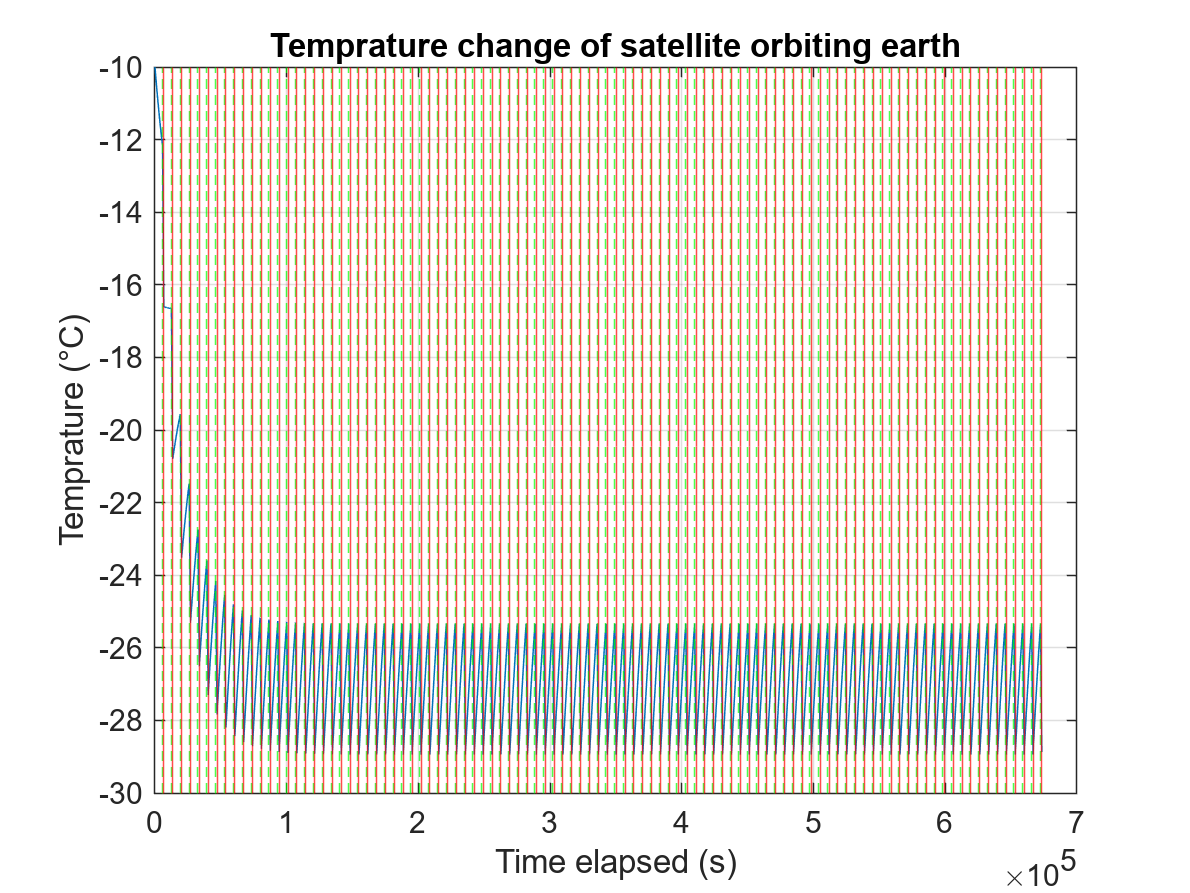

figure (1)
plot(Time_elapsed,T_sat -273.15)
hold on
xlabel("Time elapsed (s)")
ylabel("Temprature (°C)")
title ("Temprature change of satellite orbiting earth")
for i= 1:iterations
     xline(i*orbital_period_TH-eclipse_time, '--g')
     xline(i*orbital_period_TH,'r')
 end
grid on
hold off

Disscussion

figure (2)
plot(Time_elapsed,T_sat_Heater -273.15)
hold on
xlabel("Time elapsed (s)")
ylabel("Temprature (°C)")
title ("Temprature change of satellite orbiting earth with heater")
grid on
 %for i= 1:iterations
     %xline(i*orbital_period_TH-eclipse_time, '--g')
     %xline(i*orbital_period_TH,'r')
 %end
hold off

**Discussion:**

**5 Orbits (No Heater)**

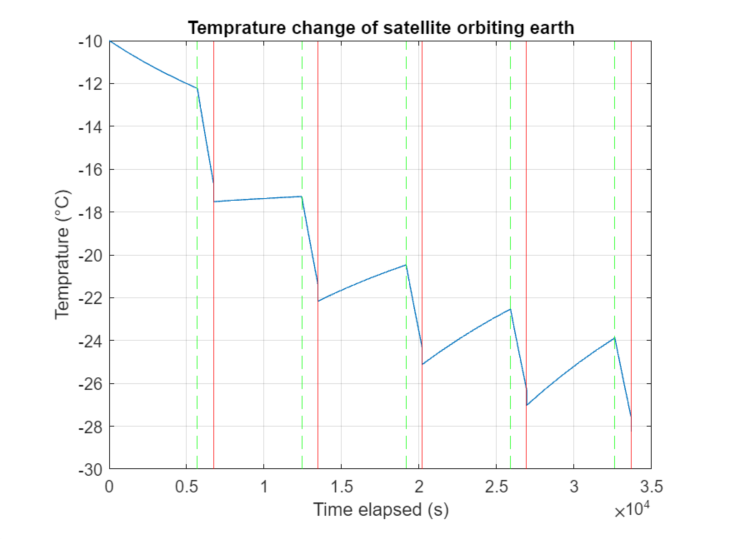

**50 Orbits (No Heater)**

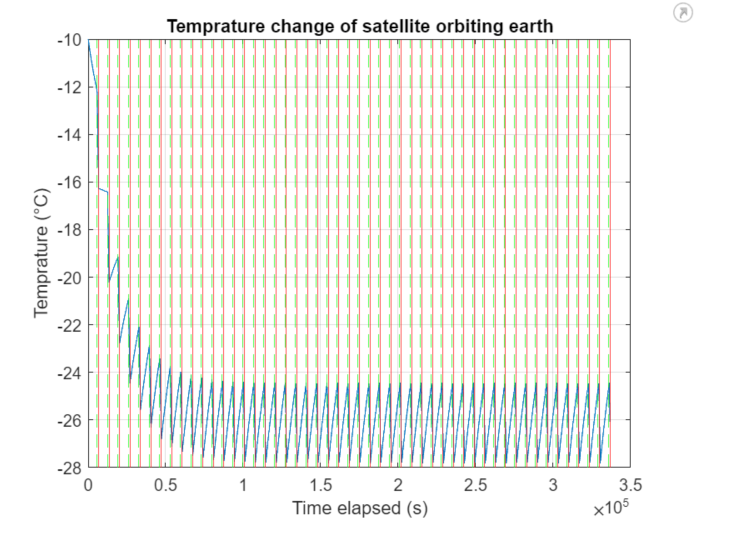

**100 Orbits (No heater)**

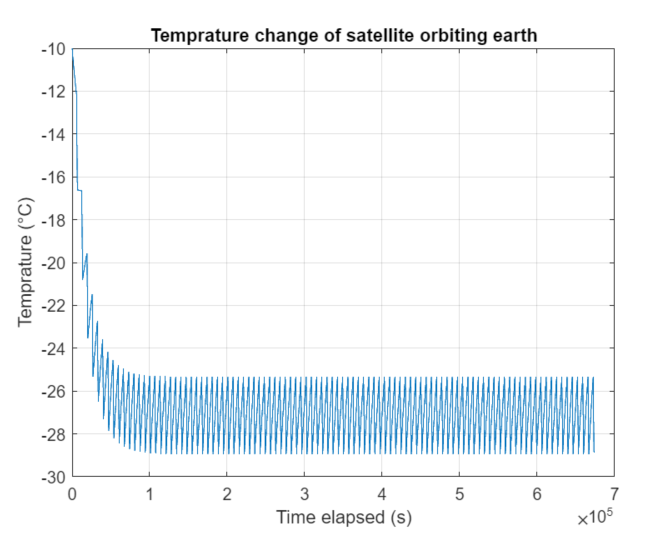

Analysing the graph we can see that the spacecraft components will not be able to survive on orbit with the current thermal control measures as it can only function between the temperatures of -15 ◦C and 30 ◦C.  We can see even in 5 orbits the temperature of the satellite gets as cold as -28 degrees and over time, looking at 100 orbits it reaches about -29 ◦C which is its coldest temperature and does not get colder.

Because of this I have chosen to add a heater. The graphs of which are shown below. 

**For Heater:**

5 Orbits with heater:

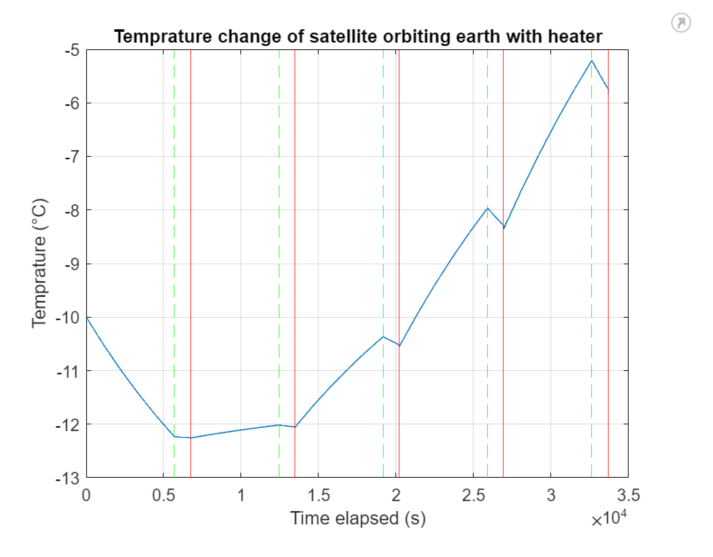

50 Orbits with heater:

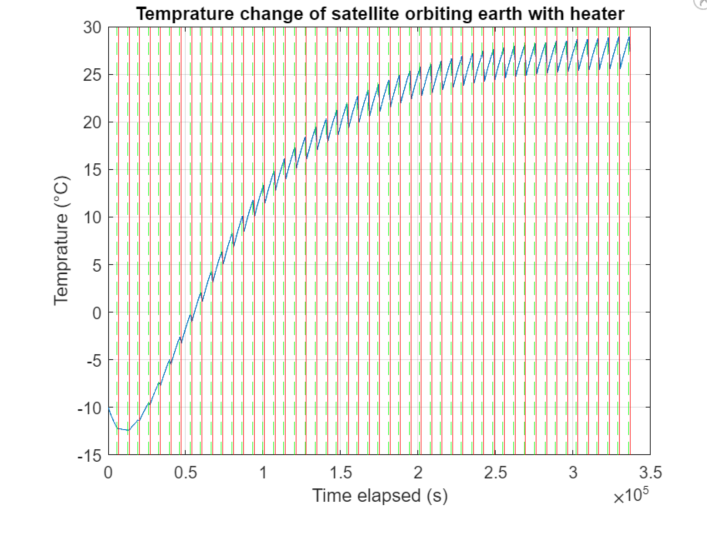

100 Orbits with heater:

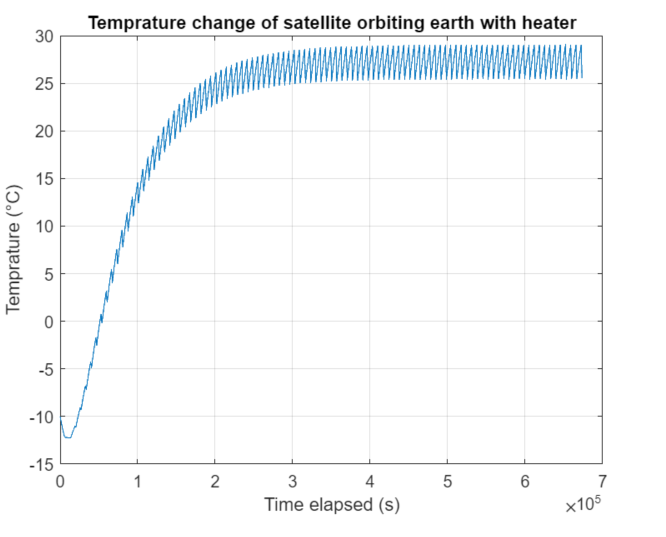

I have added a 5kg Heater with a Power of 30W. I chose a vlaue of 30W because it is lowest possible power that will keep us in the temperature range and also give us enough power to provide more heat incase of a malfunctions or changes to the space enviroment. A heater is better suited for this satellite as it allows us to have more control over the heating controls on board the spacecraft, it also means that testing and swapping materials does not need to be considered as it can be more expensive to swap and test materials.The heater is reasonably lightweight and compact, minimizing the impact on the overall weight and size of the satellite. Changing materials might require adding bulk or weight to the satellite, which could affect its efficiency and payload capacity. Integrating a heater is typically a quicker solution than redesigning and testing new materials. Time is often a critical factor in satellite development and deployment, making a rapid and effective solution preferable.

### **Conclusion**

This LiveScript has covered the completion of tutorial 2 as part of the AERO21111 Space Systems MATLAB coursework.

During the course work I have identified the required equations for Thermal Equilbirum Temperatures and the Power in from the sun and during the eclipse range. I have used these calculations to then plot a graph over several orbital periods to visualise the temperature change . Using these calculations I conducted an analysis and suggested that it would be best to use a heater on this mission, I demonstrated this with the analysis of the graph and also suggest reasons why it is better than changing the material

I have documented at every point what I have done and given an explanation of each step that was required to analyse the temperature changes and show the effects of a heater.

# Attitude Determination and Control System

### Introduction

This LiveScript covers the response to MATLAB tutorial 3 as required for the AERO21111 Space Systems module. During the course of this document I will analyse Attitude of the satellite and determine its change in torque over the course of its orbit. I will then suggest a control system that can be used to then control the attitude of the spacecraft that is suitable for the satellite, in turn analysing the effect of adding the control system.

### Task 1: Defining Constants 

Firstly we will define the constants and the various inputs that are needed for our code.

Note since we have a range of altitudes and a range of densities we have put them in arrays so we can call them later in the code.

R_e     = 6371*10^3;                        %[m] Radius of the Earth 
mu      = 3.986*10^14;                      %[m^3/s^2] Standard Gravitational Parameter
hTorque = [1000,1336,2000].*10^3;           %[m] Array of Altitudes
I_zz    = 40;                               %[kg/m^2] Mass Moment of intertia about the z-axis
I_yy    = 25;                               %[kg/m^2] Mass Moment of intertia about the y-axis
rho_ADCS  = [3*10^-15, 8.5*10^-16, 7*10^-17]; %[kg/m^2] Array of Density
C_d     = 2.2;                               %[] Coefficent of Drag
A_cross = 3.35;                               %[m^2] Cross sectional Area of the Satellite
d_CoM   = 0.5;                               %[m] Distance from center of mass to center of aerodynamic pressure


Incorrect use of '=' operator. Assign a value to a variable using '=' and compare values for equality using '=='.

### Task 2 - Task 8: Calulating Torque due to Gravity

Next we want to create a loop that will run as amny times as the number of elements in the altitude array. Before we calculate tourque due to gravity we will set up a loop that will run sa many times as the number of elements in the altitude array. Using the MATLAB *index *function and *length* function we cant then set up the loop that it runs for the length (number of elements) in the array.

Later in the code we have functions for $T_G$ which uses $R_o$ (Radius of Orbit), since Torque due to gravity is dependent on the radius of orbit so we will write the code for these varibles now using their respective equations:

### 
$$R_o =R_E +h$$


- $R_o$ is Radius of Orbit

- $R_e$ is Radius of Earth

- $h$ is altitude

index = length(hTorque);                  %Sets up the length of the loop
R_o = R_e + hTorque;                      %[m] Array for Radius of Orbit

We also know that Torque due to Drag is dependent on the orbit velocity so we will calculate orbit velocity using Equation 3.8 from the Course Notes:

### 
$$v=\sqrt{\frac{\mu \;}{r}\;}$$


- $v$ is orbital velocity

- $\mu$ is the graviational parameter

- $r$ is the Radius of Orbit, in this case the specified altitudes given in the brief

V_o = sqrt(mu./hTorque);            %[m/s^2] Orbital Velocity

We can then use a loop to calculate $T_G$ and $T_D$ for each altitude using the pointer `i` to select the altitude in the array, then with every loop it works its way through to the end of the array where the loop terminates. Below I have setup two arrays, one for $T_G$ and another for $T_D$ which calls the function (placed at the end of the code) and calculates the desired output.

for i = 1:index
    [T_G(i)] = get_Tg(I_zz,I_yy,R_o(i),mu);                     %[N/m] Uses the function to output Torque due to Gravity and forms an Array of Torque due to Gravity    
    [T_D(i)] = get_Td(rho_ADCS(i),C_d,A_cross,V_o(i),d_CoM);    %[N/m] Uses the function to output Torque due to Drag and forms an Array of Torque due to Drag
end

### Task 9: Calculating Orbital Period 

In order to calculate the Orbital Period we will use Equation 3.9 from the Course Notes:

### 
$$\tau =2\pi \;\sqrt{\frac{r^3 }{\mu }}$$


- $\tau$ is Orbital Period

- $r$ is the Orbital Radius where $r=R_E +h$ since we are assuming a circular orbit where Eccentricity is 0

- $\mu$ is the Gravitiational Parameter

Array_orbital_period = 2 * pi *sqrt((R_o.^3)./mu);  %[s] Orbital Period 

### Task 10 - Task 13: Calculate Total Torque over time

Now we need to calculate the Total Torque over time. In order to this we are going to use the `@ - function handle` function in MATLAB to create a function that will calculate the total torque over time. `Function handle `allows us to define a function inside the main script. Since $T_G$ varies over time we can use Equation 2 from the Tutorial Sheet:

### 
$$f\left(t\right)=\cos \left(\frac{t}{\tau }2\pi \;\right)T_G +T_D$$


Below I have also created a for loop that will calculate the Angular Momentum using the Total Torque function. The Angular Momenutm has been calculated using the `intergral` function, as it has to be evaluated over the orbital period.

for k = 1:index                                 
    orbital_period_A = Array_orbital_period(k);   %Creates an Array of Orbital Periods for the Range of specified Altitudes 
    Torque_g = T_G(k); 
    Torque_d = T_D(k);


Total_Time = @(t)cos((t./orbital_period_A)*2*pi)*Torque_g + Torque_d;
    thetaMomentum(k) = integral(Total_Time,0,Array_orbital_period(k));
    x = linspace(0,Array_orbital_period(k),1000);

Next I have plotted graphs to show the change in torque over time for each of the specified altitudes. Plotting time in orbital period against total torque we can see the changes in total torque, I have also displayed the angular momentum at each of the altitudes below its respective graph.

figure 
area(x,Total_Time(x));
xlabel("Time in Orbital Period")
ylabel("Total Torque")
plotTitle = ['Torque Change over Orbit Time at Altitude ', num2str(hTorque(k)/1000), ' km'];
title(plotTitle);
AngularMomentumInf = ['Angular Momentum At ',num2str(hTorque(k)/1000), 'km is ' ,num2str(thetaMomentum(k))];
disp(AngularMomentumInf);
end

### *Included at end of coursework as well*

### Task 4-5: Create a function to calculate Torque due to gravity

In task 4-5 we are required to create a function that calculates Torque due to gravity. Using the MATLAB *function, *we can create a function that takes in values for $I_{\textrm{zz}}$,$I_{\textrm{yy}}$,$R_o \;\left(\textrm{Radius}\;\textrm{of}\;\textrm{Orbit}\right)$,$\mu$ and gives us a value for $T_G$ (Torque due to gravity). 

 Using Equation 9.6 from the Course Notes;

### 
$$T_{\textrm{Qg}} =\left(\frac{3\mu }{2R^3 }\right)\left|I_{\textrm{ZZ}} -I_{\textrm{YY}} \right|\;\sin \left(2\vartheta \right)$$


- $\mu$ is the gravitiational parameter

- $R$ is the Radius of Orbit 

- $I_{\textrm{ZZ}}$ is the Mass Moment of Inertia along the Y-Axis

- $I_{\textrm{YY}}$ is the Mass Moment of Inertia along the X-Axis 

- $\vartheta$ is the angle betweeen the spacecraft body Z axis and the local vertical. In this case we have assumed that the Z-axis of the spacecraft and the local vertical have an angle of 45 degrees between them.

%function [T_G] = get_Tg(I_zz,I_yy,R_o,mu)
%T_G = ((3 * mu)/(2 * (R_o^3))) * abs(I_zz-I_yy) * sin(pi/2)
%end


### *Included at end of coursework as well*

### Task 7: Create a function for Torque due to Drag

We assumed that the only external Torques acting on the spacecraft are torque due to Drag.

Using Equation 1 from the Tutorial Sheet:

### 
$$T_D =\frac{1}{2}\rho C_d {\textrm{AV}}^2 \left(C_{\textrm{pa}} -C_g \right)$$


- $T_D$ is Torque due to Drag 

- $\rho \;$is Density 

- $C_d$ is the coeffiecent of drag

- $A$ is the cross-sectional area of the spacecraft

- $V$ is the Velocity of the Orbit

- $\left(C_{\textrm{pa}} -C_g \right)$ is the distance from the center of mass to the center of gravity

%function [T_D] = get_Td(rho_ADCS,C_d,A_cross,V_o,d_CoM)
%T_D = 0.5 * rho_ADCS * C_d * A_cross * (V_o^2) * d_CoM
%end

## **Discussion**

### 1) What changes could be made to the satellite to stop the torque from varying across the orbit?

Many things could be done to stop the torque from varying across the orbit. One of the main reasons the torque varies is because of the torque due to gravity which changes with altitude. Several ways to reduce the change are:

**Spin-stabilised spacecraft:**

- A simple and cost-effective way to reduce torque, it relies on momentum bias to achieve gyroscopic rigidity.

- Spin distributes the solar thermal input equally

- Spin axis has to be in a direction that will not change during the mission which means that correcting the satellite path if it goes off course would prove difficult.

- Creates problems with the direction the antennas are pointing so may hinder communication stability

- The mass distribution should have a symmetrical distribution which could prove a constraint when building the spacecraft. Also means that there is limited physical space for the payload.

- Instability Node nutation is also a disadvantage as oscillations of the spacecraft could become more unstable over time due to the mass distribution.

**3-Axis Stabilised spacecraft:**

- Manoeuvrability in 3-axis

- Momentum wheel on pitch axis provides momentum bias

- Expensive due to many physical systems that have to implemented

- Uses reaction and Momentum wheels which come with there own set of restraints

**Active Control Systems;**

- Reaction and Momentum wheels can store momentum to allows to offset any disturbances

- Control Moment Gyros and things like magnetic torques can be used to actively adjust the spacecraft's orientation

- Thrusters can also be used to counteract external torques. Firing these thrusters in specific directions, the spacecraft can generate torque and adjust its orientation. Paired with Reaction and Momentum Wheels we can have precision control.

- Power consumption is increased which means that batteries or more solar panels need to be added to the spacecraft which would increase the overall mass of the satellite.

- Adding more systems increases the complexity of the satellite's control system which increases the risk of malfunctions and reduces overall reliability.

- More expensive to implement 

**Passive Damping Systems:**

- Magnetic or fluid dampers passively absorb and dissipate unwanted torques

- We have no direct control over Passive systems which can make corrections harder to implement

### **2) **In this model we have neglected the disturbance torques due to magnetic effects and solar radiation. Is this a reasonable assumption?

Considering that our spacecraft operates on Low Earth Orbit (LEO) then it may experience solar radiation. Solar radiation pressure results from the momentum transfer of photons from the Sun to the spacecraft's surface. In LEO, where the spacecraft is exposed to direct sunlight, this radiation pressure can induce a force on the spacecraft. This force affects the spacecraft's orbit, potentially leading to changes in altitude, eccentricity, and inclination. Solar radiation also exerts torques on the spacecraft which can make it challenging to maintain stable orientation, which is why it is important to implement torque reducing systems.

Again, because the Sentinel-6A is in a LEO it is important to account for the disturbances torques due to magnetic effects. Due to the spacecraft being in an LEO it is primarily due to the Earth's magnetic field, the interaction between the Earth's magnetic field and the magnetic moments/magnetic stabalisation systems can cause forces that then may rotate the spacecraft and cause it to change in attitude and defer the spacecraft from its path.

### 3) Suggest a suitable attitude control system for the spacecraft based on your results?

Reaction wheels are the most suitable in this case as they effectively allow us to change the attitude of the spacecraft and give us precise control over the effects of torque. The reaction wheel should have enough torque to correct the max. torque we found in the graph which is about ~2.5 and have an angular momentum close to our max angular momentum which was found at an altitude of 1000km 0.013876.

Considering this I have decided to go with the Reaction Wheel by CubeSpace Satellite Systems (Part No.: CW0162), it has a torque of 0.012 nNm and can achieve an angular momentum of 0.0162. The reaction wheel is small in size so there in no need to compromise on payload space and it is very light coming in at only 144g. The component operates in temperatures from -20 to 80 Degree C which is more than enough for the operating range of the satellite which is -15 to 30 Degree C (Seen in Tutorial 2). More than this the reaction wheel has a very low power consumption (0.336 to 16.5 W) which means that we do not need to increase battery size and there is no reason to divert power from the parts of the spacecraft that require it.

### Conclusion

This LiveScript has covered the completion of tutorial 4 as part of the AERO21111 Space Systems MATLAB coursework.

During the coursework I have identified the necessary equations in order to calculate Torque due to Drag and Torque due to Gravity. I have created functions for these calculations and applied them over an array of altitudes. I have then used the output of each of the respective altitudes to plot a graph of time in orbital period against total torque and also displayed the angular momentum of the spacecraft at each of these altitudes. I have also discussed the changes that could be made to the satellite to stop the torque from varying across the orbit. I suggested that disturbance torques due to magnetic effects and solar radiation should not be neglected. I have also suggested a suitable attitude control system for the spacecraft based on my results.

I have documented at every point what I have done and given an explanation of each step that was required to calculate the Torque change and determine the attitude of the spacecraft.

# Communications Link Budget Analysis

### Introduction

This LiveScript covers the response to MATLAB tutorial 4 as required for the AERO21111 Space Systems module. I will calculate the Link Margin for the specified Antennae. Using these calculations I will conduct an analysis and suggest the best antenna to use for the mission by using a graph that compares the link margins of the antennas. I will suggest a parameter which would be best suitable to change by a factor of two to benefit the link budget.

### Task 1: Identify the transmitting station

The transmitting station is the satellite and the ground station is the receiver. The orentation is in a downlink configuration with the satellite transmitting the imaging data it takes to the ground station

### Task 2: Defining the Constants

Since we have been given a large number of constants, we need to define them as variables to be used in our code. Below all the nessary information table has been defined in group which will make it easier to refer back to varibles as we code.

%Property of ground station (GS)
P_Tgs        = 35;   %[W] GS Transmission Power
T_Rgs        = 257;  %[K] GS Noise temperature
D_gs         = 4.5;  %[m] GS Antenna diameter

%Property of platform comms link
BER         = 8*10^-6;   % Bit Error Rate
R_b         = 150;       %[Mbps] Transmission Rate
v_d         = 8.9;       %[GHz] Downlink frequency 
L_i         = 1.85;      %[dB] Implementation losses 
L_add       = 7;         %[dB] Additional losses

%Property of Space Segment (SS) 
P_Tss_P     = 30;       %[W] Transmission Power for Parabolic Antennae  
P_Tss_He    = 90;       %[W] Transmission Power for Helix Antennae
P_Tss_Ho    = 54;       %[W] Transmission Power for Horn Antennae

T_Rss_P     = 156;      %[K] Noise Temperature for Parabolic Antennae
T_Rss_He    = 160;      %[K] Noise Temperature for Helix Antennae
T_Rss_Ho    = 170;      %[K] Noise Temperature for Horn Antennae

theta_bw_P  = 35;       %[°] Antenna Beamwidth for Parabolic Antennae
theta_bw_He = 30;       %[°] Antenna Beamwidth for Helix Antennae
theta_bw_Ho = 33;       %[°] Antenna Beamwidth for Horn ANtennae

SS_mass_P   = 30;       %[kg] Mass for Parabolic Antennae
SS_mass_He  = 12;       %[kg] Mass for Helix Antennae
SS_mass_Ho  = 2;        %[kg] Mass for Horn Antennae

k    = 1.38*10^(-23); %[J/K] Boltzmann Constant 

P_TransPower_Array = [P_Tss_P,P_Tss_He,P_Tss_Ho]; %[W] Array containing the three values of transmission power, one for each type of antenna.

### Task 3: Selcting Appropriate Equations to Calculate Antenna Gain 

Next we have to find the equations to calculate gain. Antenna Gain ($\left.G_T \right)$ can be defined as the ratio of power from an effective isotropic radiator, EIRP to actual transmitter power. As we have three types of antenna we need to find three different equations since the antennas are of different shapes.

#### For Parabolic Antennas,

From Equation 8.20 from the Course Notes:

### 
$$G=17\ldotp 8+20\log \;D+20\log \;f$$
 

or from Equation 8.21 and Equation 8.19 from the Course Notes:

### 
$$\begin{array}{l}
G=44\ldotp 3-10\log \left(\theta {\;}^2 \right)\\
\theta =\frac{21}{f\;D}
\end{array}$$


- $G\;$is the Gain of the Parabolic Antenna 

- $D$ is the diameter of the parabolic satellite

- $f$is the frequency in GHz

- $\theta \;$is the antenna beam width 

#### For Helix Antennas,

From Equation 8.18 from the Course Notes:

### 
$$G=20\log \left(\frac{\pi^2 D^2 L}{\lambda^2 }\right)$$


From Equation 8.17 form the Course Notes:

### 
$$\theta =\frac{52}{\sqrt{\left(\frac{\pi^2 D^2 L}{\lambda^2 }\right)\;}}$$


- $G\;$is the gain of the Helix antenna 

- D is the diameter of the Helix satellite 

- $\lambda \;$is the wavelength of the Carrrier wave

- L is the length of the Helix

#### For Horn Antennas,

From Equation 8.16 from the Course Notes:

### 
$$G=20\log \left(\frac{\pi \;D}{\lambda \;}\right)-2\ldotp 8$$


From Equation 8.15 in the Course Notes:

### 
$$\theta =\frac{255\lambda }{\pi \;D}$$


- $G\;$is the gain of the Horn antenna 

- D is the diameter of the Horn satellite 

- $\lambda \;$is the wavelength of the Carrrier wave

### Task 4: Calulating Gain of Available Antennas at the transmitting segment 

Using the identified equations we can find the gain for each of the satellites, firstly the eqautions need to be rearranged so we can find the gain as a function of variables that we do have, in this case Antenna Beam Width:

#### Considering Parabolic Gain,

From Equation 8.21 from the Course Notes:

### 
$$G=44\ldotp 3-10\log_{10} \left(\theta {\;}^2 \right)$$


Gain_P  = 44.3 - (10*log10((theta_bw_P)^2));      %[dB] Gain of Parabolic Antenna 

#### Consdidering Helix Gain,

By re-arranging Equation 8.17 and Equation 8.18 from the Course Notes:

### 
$$G=10\ldotp 3+10\log \left({\left(\frac{52}{\theta \;}\right)}^2 \right)$$


Gain_He = 10.3 + 10*log10((52/theta_bw_He)^2);    %[db] Gain of Helix Antenna 

#### Considering Horn Gain,

By re-arranging Equation 8.15 and Equation 8.16 from the Course Notes:

### 
$$G=20\log \left(\frac{255}{\theta \;}\right)-2\ldotp 8$$


Gain_Ho = 20*log10(255/theta_bw_Ho) - 2.8;              %[dB] Gain of Horn Antenna

Finally we put all the gains that have been calualted into to an array to use for later in our code calculations

Gain_Array = [Gain_P,Gain_He,Gain_Ho];          %[dB] Array of Calculated Gains

### Task 5: Calculate Effective Istrope Radated Power (EIRP)

EIRP, Effective Isotrope Radiated Power is the total power delivered to the attenna times by the Gain of the antenna. We also know that Antenna gain can be defined as the ratio of power from an effecitve isotropic radiator to actual transmitted power. So we can re-arrange the definition of antenna gain to calculate EIRP.

From Equation 8.9 in the Course Notes:

### 
$$G_T =\frac{\mathrm{EIRP}}{P_r }$$


Re-arranging this we can get Equation 8.10 in the Course Notes

### 
$$\mathrm{EIRP}=G_T P_r$$


- $G_T \;$is the Gain of the transmitter 

- $P_{T\;}$is the power of the transmitter

Then by using the law of logarithims we can add the gains of the Antenna to the log of the Transmission Power, 

### 
$$\mathrm{EIRP}=G_T \;+10\log_{10} \left(P_T \right)$$


Also remembering to make the output of this calulation an array.

EIRP_Array = Gain_Array + 10*log10(P_TransPower_Array);     %[W/m^2] Array of EIRP calulated for each Antenna 

### Task 6: Calculate Gain at Receive Station

Now we are on to calculating the Gain at the Receive station which is the ground station since the system is in a downlink configuration. Since the ground station is using a Parabolic Antenna we can use the equation for Gain of a parabolic antenna. We can use Equation 8.20 from the course notes since we have been given Downlink Frequency and Antenna Diameter.

From Equation 8.20 from the Course Notes:

### 
$$G=17\ldotp 8+20\log \left(D\right)+20\log \left(f\right)$$


- $G$ is the Gain

- $D$ is the diameter of the Parabolic Antenna 

- $f$ is the downlink frequency

Gain_GS = 17.8 + 20*log10(D_gs) + 20*log10(v_d);           %[dB] Gain at Receive Station

### Task 7: Calculate Gain-to-Noise Ratio

We also need to calculate the Gain-to-Noise Ratio. The GRN0R (Gain-to-Noise Ratio) can be defined as the ratio between the Gain at the Recieve Station divided by the Noise Temperature multiplied by the Boltzmann Constant.

### 
$$\textrm{GRN0R}=\frac{G_R }{{\textrm{kT}}_R }$$


- $\textrm{GRN0R}$ is the Gain to Noise Ratio

- $G_R$ is the Gain at the Recieve Station

- $T_R$ is the Noise Temperature

- $k$ is the Boltzmann Constant

By using the law of logs we can again convert it into logarithimic form:

### 
$$\left(\frac{G_R }{{\mathrm{kT}}_R }\right)=10\log_{10} \left(G_R \right)-10\log_{10} \left(T_R \right)-10\log_{10} \left(k\right)$$


This will give us the ratio in units of dB.

NB: Gain at Receiving Station is in units of dB and therefore does not need to be put into a log.

GRN0R_GS = Gain_GS - 10*log10(T_Rgs) - 10*log10(k);     %[dB] Gain-to-Noise Ratio 

### Task 8: Defining the Slant Range

Now we want to calculate the free space loss, before that we have to calculate the the slant range to the spacecraft across the given alititudes. 

Firstly we will create an arry covering an altitude range with an appropriate step size. In the brief we are given that range of alitudes for the link budget is from 250km to 2500km and so we shall set that as our range, I have decided to choose a step size of 100. Below I have used an *linspace* function to implement the range of altitude into my code: 

H_Range = linspace(250000,2500000,100); %[m] Range of Altitudes from 250km to 2500km

Next we can use the Equation in the tutorial sheet in order to find the slant range, which can be defined as the distance between the spacecraft and the ground station;

### 
$$S=\sqrt{{\left(R_e +h\right)}^2 -{R_e }^2 }$$


- $S$ is the Slant Range

- $R_e$ is the Radius of the earth 

- $h$ is the altitude of the spacecraft

S      = sqrt(((R_e + H_Range).^2)-(R_e)^2);  %[m] Slant Range in Worst Case Senario 

### Task 9: Calculate Free Space Loss

To calculate Free Space Loss we can use the Slant Range calculated above. Free space loss is loss due to energy dissipation over a greater area.

From Equation 8.30 in the Course Notes:

### 
$$L_{\mathrm{FS}} ={\left(\frac{4\pi \;S}{\lambda }\right)}^2$$


- $L_{\textrm{FS}} \;$is free space loss dB

- $S$ is the Slant Range 

- $\lambda$ is the wavelength in meters

We can calculate the wavelength from:

### 
$$\lambda =\frac{c}{f}$$


- $c$ is the speed of light

- $f$ is the downlink frequency 

lambda  = (3*10^8)/(v_d*10^9);                %[m] Wavelength
L_FS    = 20*log10((4*pi*S)./lambda);         %[dB] Free Space Loss

### Task 10: Estimate the Carrier to Noise Density Ratio

We can now calculate the Carrier to Noise Density Ratio through the Link Budget Equation.

From Equation 8.32 in the Course Notes:

### 
$$\frac{C}{N_O }=\frac{P_T G_T G_R }{L_{\mathrm{FS}} L_{\mathrm{add}} {\mathrm{kT}}_R }=P_T G_T G_R \left(\frac{1}{L_{\mathrm{FS}} }\right)\left(\frac{1}{L_{\mathrm{add}} }\right)\left(\frac{1}{k}T_R \right)$$


We can then re-write the Carrier to Noise Density Ratio because we know that 

### 
$$\begin{array}{l}
\textrm{EIRP}=P_T G_T \\
\textrm{GRN0R}=\frac{G_R }{{\textrm{kT}}_R }
\end{array}$$
 
$$\;\;\;\;\;\;\Longrightarrow$$
 
$$\frac{C}{N_0 }=\mathrm{EIRP}+\mathrm{GRN0R}+\left(\frac{1}{L_{\mathrm{FS}} }\right)\left(\frac{1}{L_{\mathrm{add}} }\right)$$


From our previous calculations we know that these terms are already in there logarithimic form so we can then re-write this equation as: 

### 
$$\frac{C}{N_O }=\mathrm{EIRP}+\mathrm{GRN0R}-L_{\mathrm{FS}} -L_{\mathrm{add}}$$


The Link Budget Equation puts all the gains and losses (Losses due to energy dissapation, Atmospheric absorption, and additional losses)

CN0R_P = EIRP_Array(1)+GRN0R_GS-L_FS-L_add;     %[] CN0R for Parabolic Antenna 
CN0R_He = EIRP_Array(2)+GRN0R_GS-L_FS-L_add;    %[] CN0R for Helix Antenna
CN0R_Ho = EIRP_Array(3)+GRN0R_GS-L_FS-L_add;    %[] CN0R for Horn Antenna
CN0R = [CN0R_P;CN0R_He;CN0R_Ho];                %[] Array of CN0Rs

### Task 11: Find Energy per Bit Noise Density Ratio

Using our calculated CN0R and the given transmission rate, we can find the energy per bit noise density ratio (EBN0) fr our antenna systems across the required altitudes.

We can use Equation 8.23 from the Course Notes to first find the time to receive one bit and then use that in Equation 8.25 from the Course Notes to find the Energy per Bit Noise Density Ratio.

From Equation 8.23 from the Course Notes:

### 
$$t_b =\frac{1}{R_b }$$


- $t_b \;$is the time to recieve one bit

- $R_b$ is the data rate

From Equation 8.25 from the Course Nottes:

### 
$$\frac{C}{N_0 }=\frac{E_b }{N_0 }R_b$$


- $\frac{C}{N_0 }$ is the signal to noise ratio

- $E_b$ is the energy per bit 

- $R_b$ is the data rate 

Using these equations we can re-arrange to form an equation that will give us the Energy per Bit Noise Density Ratio:

### 
$$10\log_{10} \left(\frac{E_b }{N_0 }\right)=10\log_{10} \left(\frac{C}{N_0 }\right)-10\log_{10} \left(\frac{1}{t_b }\right)$$


t_b = 1/(R_b*10^6);                             %[s/Mb] Time to recieve one Bit
Eb_N0 = CN0R - 10*log10(1/t_b);                 %[dB] Energy per Bit Noise Density Ratio

### Task 12: Find the probability of Error

Moving onto link quailtiy requirements, we want to now calculate the probability of Error. Firstly, we are going to set up a sensible range (in this case between 0 - 15 dB) of potential values of EBN0.

Eb_N0_estm  =linspace(0,15,100);    %[dB] Estimation Array

Then, for the fiven modulation scheme (DPSK) the probability of error for a single but it given by the following equation in the tutorial sheet:

### 
$$P_e =\frac{1}{2}e^{-{10}^{\left(\frac{E_b }{N_{0\;\textrm{BER},\textrm{est}} }\times \frac{1}{10}\right)} }$$


Using the array of potential values for estimation we can then write the code below:

P_e = 0.5*exp(-10.^(Eb_N0_estm.*(1/10)));   %[] Probability of error for a single orbit 

### Task 13: Find the appropriate EBN0 that best match the required BER

Once we have calulated the probability of error we now have a range of EBN0 measurements that are correlated with a probability. To identify the appropriate EBN0 that best matches our required Bit Error Rate we can interpolate between the EBN0 measurements. 

Eb_N0_Opt =  interp1(P_e,Eb_N0_estm,BER); %[] Best match EBN0 that matches required Bit Error Rate

###  Task 14: Determine the Link Margin for all the Available Antenna Systems 

The final calculation is to determine the link margin for all the avaible atenna systems. This is done by subtracting the required modulation EBN0 and any impl from the overall link budget EBN0. This will give us the link margin across the defined Altitude Range, which will give us the link quailty.

Link_Margin = Eb_N0-Eb_N0_Opt-L_i;        %[dB] Link Margin

### Task 15: Display the resultant link margin values across the given altitude

The Link Margin can drawn against the Altitude Range Array showing the change in downlink margins as the altitude of satellite increases.

H_Range_Km = H_Range / 1000;    %[m] Changes the range of Altitudes from Kilometers into Meters 
plot(H_Range_Km,Link_Margin);   % Plots the Altitude Range against Link Margin
% S_H_y   = linspace(-10,15,100); % A range of y-values to show where the spacecraft orbit 
% S_H_x   = ones(1,100);          % A range of x values to show where the spacecraft orbut 
hold on                         % Hold the graph
grid on                         % Adds a grid
% plot(S_H_y,S_H_x,"k")
xline(1336);
xlabel("Altitude (km)")         % Labels the x-axis of the graph
ylabel("Link Margin (dB)")      % Labels the y-axis of the graph
v1 = [0 -6; 0 0; 2500 0; 2500 -6;];
f1 = [1  2 3 4];

patch('Faces',f1,'Vertices',v1,'FaceColor','red','FaceAlpha',.1);
legend("Parabolic Atenna","Helix Antenna","Horn Antenna", "Alitiude of Orbit", "Unsuitable Link Margin") % Adds a legend to the graph which labels the coloured lines 
title("Downlink Margin for Different Antennas")     %Adds Title to the graph 
set(gca,"Xtick",0:H_Range_Km(end)/5:H_Range_Km(end)) % Set boundary for the x-axis between our desired altitudes

## Discussion:

### 1) Based on your analysis are all avaible systems sutiable for use in the Sentinel-6B mission at the chosen orbital altitude?

From our graph and analysis we can see that not all the availble antenna systems are suitable for use in the Sentinel-6B mission at the chosen orbital altitude, we see that even at the given orbital alitutde of 1366km not all antennas fit the requirements.

Parabolic: **Unsuitable**

- We see from the graph that at the Parabolic Antenna has a negative link margin even at the given orbital altitude of 1336km, since we want our mission orbital altitude to range from 250km-2500km this makes in unsuitable for our mission. The negative link margin means that the Ground Station will be unable to download data as the signal will be too weak.

Helix : **Suitable**

- Has a positive Link Margin at given orbital altitude and so meets the minimum Link Margin requirement for the Mission

Horn: **Suitable**

- Has a positive Link Margin at given orbital altitude and so meets the minimum Link Margin requirement for the Mission

### 2)  What Antenna System would you recommend and why?

We have the choice between the Helix antenna and Horn antenna since they are the only suitable ones that meet the mission requirements.

Horn Antenna:

- **Pros:** 

- Meets Mission Requirments

- Lighter mass compared to Helix Antenna. Horn Antenna weighs 2kg.

- Has a wide frequency range from 300MHz - 30GHz

- **Cons:**

- Lower effciency rating compared to Helix Antenna

- Produces less Gain due to lower efficiency rating compared to Helix Antenna

Helix Antenna:

- **Pros:**

- Meets Mission Requirments

- Higher efficiency due to shape and structure compared to Horn Antenna

- Producess more Gain due to higher efficiency comparted to Horn Antenna

- **Cons:**

- Heavier Antenna than Horn Antenna. 12kg for the Helix Antenna compared to 2kg.

- Narrower frequency Range from 300MHz - 3 GHz

From the anaylsis I would recommed the Helix Antenna system. Especially considering the fact that Helix Antenna keep a postive link margin across the whole range of altitudes for the 250km to 2500km, which is the required altitude range for the mission, unlike the Horn Antenna. This means that if the Satellite defers from its orbital path and goes either higher or lower than its desired altitude, since it has a positive link margin for a large range of altitudes it will still have the ability to communicate with the ground station and send and receive data. In my opinion this makes it the better choice. Although the Helix Antenna has a narrower frequency range compared to the Horn Antenna, it is more efficient and produces a higher gain. Therefore, I believe that the Helix Antenna is the best systems to pbe installed on the Sentinel-6B mission.

### 3) Changing Single Link Parameters

The Mission design lead suggests that it might be possible to change a single link parameter by a factor of 2. Below are other the gound segment and space segment parameters changed by a factor of 2. Note,

**Ground Segment:**

- GS Transmission Power: 35W $\to$ 70W

- GS Noise Temperature: 257K $\to$ 128.5K (Decreased by a factor of 2)

- GS Antenna Diameter: 4.5m $\to$ 9m

**Space Segment:**

- SS Transmission Power:

- Parabolic: 30W $\to$ 60W

- Helix: 90W $\to$ 180W

- Horn: 54W $\to$ 108W

- SS Noise Temperature:

- Parabolic: 156K $\to$ 78K (Decreased by factor of 2)

- Helix: 160K $\to$ 80K (Decreased by factor of 2)

- Horn: 170K $\to$ 85K (Decreased by factor of 2)

- SS Antenna Beamwidth($\left.\theta \right)$:

- Parabolic: 35° $\to$ 17.5°

- Helix: 30° $\to$ 15°

- Horn: 33° $\to$ 16.5°

- SS Mass:

- Parabolic: 30kg $\to$ 15kg

- Helix: 12kg $\to$ 3kg

- Horn: 2kg $\to$ 1kg

For Ground Station: 

- Increasing the Transmission Power by 2 has no effect on the Link Margin because the Ground Station and the Satellite are in a downlink configuration, the ground station is recieving and the Satellite is the one sending data. So increasing the transmission power as no effect so will not be considered.

- By decreasing the Noise Temperature by a factor of 2, the Link Margin of all the antennas increases. Graphically the Link Margin of the antenna shifts upwards but it does not provide enough of a increase to make the Parabolic Antenna a viable option, only adding about 3db to the Link Margins. The change in Noise Temprature increases the Link Margin.

- Antenna Diameter is increased by a factor of 2 and so has a large affect on the Link Margin. By increasing the Antenna Diameter the Link Margin would increase so much so that the Parabolic Antenna would become a considerable option to use in the mission, it increases the link margin by about 6db. Although increasing the antenna diameter would increase the weight of the antenna since it is the ground station it does not need to be considered.

For Space Segment:

- By increasing the Transmission Power by 2 increases the Link Margin for each antenna. However it does not have a drastic postive effect on the Link Margin, it still leaves the Parabolic Antenna as a unviable option when considering antennas that could be used for the missiom. Increasing the transmission power does mean that the satellite needs to have more power on board to accomodate the antenna, which may mean adding more components to the spacecraft, ie. batteries, solar panels, which will ultimatiley increase the mass of the Satellite. It could also mean that power would be re-routed and other components would have to use reduced power. 

- Decreasing the Noise Temperature by a factor of 2, the Link Margin is not changed so is not considered.

- Decreasing Antenna Beamwidth increases all the Link Margins by about 6db. However there are many factors that go in to changing the Beamwidth. To change the Antenna Beamwidth either the Diameter of the Satellite has to increase, this would mean that the mass of the antenna could change and therefore affect other parts of the mission. Or the wavelength of the antenna could decrease, this would mean that the frequency would have to change since frequency determines wavelength.

- Mass has no affect on link margin, although it will have effects on other parts of the mission so does not need to be considered

Considering all the changes to the single link parameters, I believe it is best to increase the Diameter of the Antenna on the Ground Station. By increasing the diameter of Antenna the Link Margin increases much more than changing any other of the single link parameters. Although it changes the mass it will not affect the mission as it is the Ground Station and also the change in frequency due to the change in diameter will not affect the mission as it is not transmitting any data it is only receiving.

### **Conclusion**

This LiveScript has covered the completion of tutorial 3 as part of the AERO21111 Space Systems MATLAB coursework.

During the course work I have identified the required equations for calculating the Link Margin for the specified Antennae. Using these calculations I conducted an analysis and suggested the best antenna to use for the mission by using a graph that compared the link margins of the antennas. I was also able to suggest which parameter would be best suitable to change by a factor of two to benefit the link budget with the smallest compromises on the mission.

I have documented at every point what I have done and given an explanation of each step that was required to calculate the Link Budget.

# Power and Mass Budget Analysis 

### Introduction

This LiveScript covers the response to MATLAB tutorial 4 as required for the AERO21111 Space Systems module. I will do an analysis of the overall power consumption and the mass budget of the satellite. I will identify what design changes have led to an increase/decrease of mass or power when comparing mass and power budgets of those of the Sentinel-6A.

### Task 1: Estimate Mission Lifetime

To estimate Mission Life time we need the Recharge Cycle and the Orbital Period. Since we know that the number of charge cycles is the number of orbits over mission life time (from Course Notes pg167), by multiplying these two values we will be given the mission life in seconds. Therefore the equation we need to use is:


$$\mathrm{Mission}\;\mathrm{Life}\;\mathrm{in}\;\mathrm{yrs}=\;\frac{\mathrm{Recharge}\;\mathrm{Cycles}\times \;\tau }{60\times 60\times 24\times 365}$$


- $\tau$ is the orbital period

I have also used the floor function in order to round down to take into account uncertainties in the space enviroment and also component degradation which could shorten the mission life.

Recharge_Cycles = 25000;  %[] Estimated number of recharge cycles before degradation

Mission_Life    = floor(((Recharge_Cycles*orbital_period_TH)/(60*60*24*365)));%[s] approximate mission lifetime to the nearest whole year

X = ['Estimated Mission Life is ',num2str(Mission_Life),' yrs (rounded down to nearest year)'];
disp(X)

Estimated Mission Life is 5 yrs (rounded down to nearest year)


### Task 2: Estimate overall power demands when in Eclipse

Before I can estimate the overall power demands I need to define the Power budget of the satellite and also the estimated performance parameters for the battery.

%Estimated Performance Parameters for the Protoype Li-ION battery
ODoD    = 0.5;    %[%] Operational Depth of Discharge
ED      = 120;   %[Whrs/kg] Energy Density
V_B     = 18;    %[V] Output volatage of Satellite Bus

%Power budget of each spacecraft subsystem 
P_Payload       = 350;   %[W] Power of Payload
P_ThermalSub    = 150;  %[W] Power of Thermal Subsystem
P_ComSub        = 240;   %[W] Power of Communications Subsystem
P_ADCS          = 110;   %[W] Power of ADCS Subsystem
P_OtherSub      = 150;   %[W] Power of All other Sub-Systems

The reaction wheel that was selected does not have a power rating and instead it has been documented with a range of power, therefore I have definied the required power for the Reaction Wheel has the average power it is documented to use, the Power of the Heater is the same as that defined in tutorial 2. The Transmission Power for Helix Antenna is that which was definied in tutorial 3.

P_ReactWheel    = 8.418; %[W] Power of Reaction Wheel
P_Heater;                %[W] Power of Heater (as definied in tutorial 2)
P_Tss_He;                %[W] Power of Transmission Power for Helix Antenna (as definied in tutorial 3)

Since the spacecraft will not be observing during the eclipse period, the overall power demands are greatly reduced. Below is a summary of the power demands during eclipse:

- The payload will be off. 

-  All thermal components will be at full power.

- The communications subsystem will not be processing any data and so only require half the defined power. 

- Transmissions will still be active due to ground station overflights and so will remain at full power. 

- The attitude control will not be needed for payload pointing and will only maintain attitude for communications antenna pointing requirements, reducing the power demands by half.

- Reaction wheels will remain fully operational at all times.

- All other subsystems will be placed into standby mode and so operate at half power.

Below these conditions have been applied

eP_Payload      = 0;             %[W] Payload will be off
eP_ThermalSub   = P_ThermalSub;  %[W] All thermal components will be at full power
eP_ComSub       = P_ComSub/2;    %[W] The communications subsystem will not be processing any data and so only require half the defined power
eP_Tss_He       = P_Tss_He;      %[W] Transmissions will still be active so will remain at full power
eP_ADCS         = P_ADCS/2;      %[W] Attitude Control Power Requirements halved
eP_ReactWheel   = P_ReactWheel;  %[W] Reaction wheel will remain fully operational
eP_Heater       = P_Heater;      %[W] Heater at full power during eclipse
eP_OtherSub     = P_OtherSub/2;  %[W] Standby Mode so operate at half power

Total_Power     = eP_Payload + eP_ThermalSub + eP_ComSub + eP_Tss_He + eP_ADCS + eP_ReactWheel + eP_Heater + eP_OtherSub; %[W] Power required by the Satellite during eclipse phase
Y = ['Total Power Required In Eclipse Period is ' num2str(Total_Power) 'W' ];
disp(Y)

Total Power Required In Eclipse Period is 528.418W


### Task 3: Total Battery Capacity 

In order to calculate Total Battery Capacity we can use the equation found in the Power Lecture Notes:


$$C_B =\frac{P_{\textrm{eclipse}} \;t_e }{\textrm{DOD}\;V_B }$$


- $C_B$ is the Total Battery Capacity

- $P_{\textrm{eclipse}\;}$is the Power Required during the eclipse period

- $t_e$ is the duration of Eclipse Period in hrs

- $\textrm{DOD}$ is the Depth of Discharge

- $V_B$ is the Voltage Bus

C_B = (Total_Power*(eclipse_time/3600))/(ODoD*V_B); %[Ah] Total Battery Capacity

### Task 4: Total Energy of Storage System

To find the Total energy stored, we can use the equation found in the Power Lecture Notes, multiplying the Voltage bus by the Battery Capacity


$$\in \;=C_B \;V_B$$
 

- $\in$ is the energy stored in Wh

- $C_B$ is the Total Battery Capacity

- $V_B$ is the Voltage Bus

Energy_storage = C_B*V_B;   %[Wh] Energy stored in the Battery

### Task 5: Calculate the mass of the Battery

Next we want to find the Mass of the Battery. We can use the equation found in the Power Lecture Notes:


$$M_{\textrm{battery}} =\frac{\in }{\bar{\in} }$$
 

- $M_{\textrm{battery}}$ is the mass of Battery

- $\in$ is the Energy Stored

- $\bar{\in}$ is the Energy Density in Wh/kg

m_Battery   = round(Energy_storage/ED)  %[kg] Mass of Battery

m_Battery = 3

## Follow on tasks:

### Task 6 - Idenify and Define Constants

Below all the constants given in table 3 are defined:

eta_Cell     = 0.2;      % Cell efficiency is 20%
D_yr         = 0.05;     % Degradation per year from initial baseline performance is 5%
eta_packing  = 0.9;      % Packing efficiency is 90%
theta_inc    = 40;       % Incident angle to the sun
V_array      = 24;       % Array output voltage [V]

### Task 7 -  Calculate charging rate

While the spacecraft is in the sunlight the spacecraft is charging. We can find the recharge rate using the equation found in the Course Notes on pg.167


$$R_{\textrm{ch}} =\frac{\textrm{DOD}\;C_B }{t_s }$$


- $R_{\textrm{ch}}$ is Battery Charge Rate

- $\textrm{DOD}$ is Depth of Discharge

- $C_B$ is Total Battery Capacity

- $t_s$ is time spent in sunlight during orbit

Time spent in sunlight was calculated in Tutorial 1 and defined as `sun_time`.

R_ch = (ODoD*C_B)/(sun_time/3600); %[hr] The Recharge Rate

### Task 8 - Calculate Total Power Of Array

Summing all the power used during the time the satellite is in the sun, we can calculate the total power demands that is required of the solar array.

Total_Power_Sun = P_Payload + P_ThermalSub + P_ComSub + P_Tss_He + P_ADCS + P_ReactWheel + P_OtherSub; %[W] Power required by the Satellite during sun phase

Total Power Required of Array can be calculated using the equation from the Course Notes on pg167


$$P_{\textrm{EOL}} =P_{\left(\textrm{payload}+\textrm{services}\right)} +R_{\textrm{ch}} V_A$$


- $P_{\textrm{EOL}}$ Total Power Required of Array at End of Life

- $P_{\left(\textrm{payload}+\textrm{services}\right)}$ Power of payload and services, in this case the total power demand that is required of the solar array (`Total_Power_Sun`)

- $R_{\textrm{ch}}$ is the Battery Charge Rate

- $V_A$ is the Array output voltage

P_EOL = round(Total_Power_Sun + (R_ch*V_array));                    %[W] Total Power Required of Array
Z = ['Total Power Required of Array is ' num2str(Total_Power) 'W' ];
disp(Z)

Total Power Required of Array is 528.418W


### Task 9 - Area of the Solar Array

To estimate the area of the solar array we can use the Equation found in the Lecture Notes:


$$P=q_s A\eta_p \eta$$


- $q_s$ is the solar insolation

- $A$ is the Area of the Solar Array

- $\eta_p$ is the packing efficiency

- $\eta$ is the cell efficiency

Re-arranging the equation to find Area:


$$A=\frac{P}{q_s \eta_p \eta \;}$$


A_Array = round(P_EOL/(q_s*eta_packing*eta_Cell));  %[m^2] Area of Solar Array


### Task 10 - Estimate the mass of the Solar Panels

For Sentinel 6A, the ratio of mass to area is $\frac{150}{15}=10$ therefore, using this we can use this ratio we find the mass of the solar panels. 

mass_array = (150/15)*A_Array;  %[kg] Mass of Solar Array

## Discussion

### Discussion


$$
\left[\matrix
{\textbf{Sub-System Element}
& \textbf{Sentinel 6-A [W]} & \quad
& \textbf{Sentinel 6-B [W]} & \quad \cr
\textrm{Payload} & 350 & \quad & 350 \cr
\textrm{Thermal Subsystem} & 150 & \quad & 150 \cr
\textrm{Heater} & N/A & \quad & 30 \cr
\textrm{Communications Subsystem} & 240 & \quad & 240 \cr
\textrm{Transmission Power} & 30 & \quad & 54 \cr
\textrm{ADCS Subsystem} & 110 & \quad & 110 \cr
\textrm{Reaction Wheels} & N/A & \quad & 8.418 \cr
\textrm{All Other Subsystems} & 150 & \quad & 150 \cr
\textrm{\textbf{Total}} & 1030 & \quad & 537.418 \cr
}\right]$$
 


$$\left[\matrix
{\textbf{Sub-System Element}
& \textbf{Sentinel 6-A [/kg]} & \quad
& \textbf{Sentinel 6-B [/kg]} & \quad \cr
\textrm{Payload and Structure} &465 & \quad & 465 \cr
\textrm{Thrusters} & 50 & \quad & 50 \cr
\textrm{Manouvering Fuel} & 130 & \quad & 130 \cr
\textrm{De-Orbit Fuel} & N/A & \quad & 779 \cr
\textrm{Thermal Subsystem} & 40 & \quad & 40 \cr
\textrm{Heater} & N/A & \quad & 5 \cr
\textrm{Communications Subsystem} & 70 & \quad & 70 \cr
\textrm{Transmission Antenna} & 30 & \quad & 12  \cr
\textrm{ADCS Subsystem} & 60 & \quad & 60 \cr
\textrm{Reaction Wheels} & N/A & \quad & 0.144 \cr
\textrm{Power Distribution System} & 50 & \quad & 50 \cr
\textrm{Power Regulation and Control System} & 70 & \quad & 70 \cr
\textrm{Energy Storage System} & 15 & \quad & 3 \cr
\textrm{Solar Array} & 150 & \quad & 50 \cr
\textrm{\textbf{Total}} & 1130 & \quad &  1784.14\cr
}\right]
$$


Within this element of Space Systems I have calculated the total mass and total power required for the Sentinel 6B mission. Althought the mass of the Sentinel 6B is 649.64kg we did add a reaction wheel to add stability and also add deorbit fuel, we also introduced a helix satellite for added communication. 

I suggested that the design team add a heater in order to keep the satellite at its operating temperature as it allows us to have a more precise control over temperature changes during the Orbit of the Satellite, changing and testing materials would be much more expensive and acts as a passive heater so there is less control over it. 

For the communications section I suggested the Helix Antenna. The Helix Antenna stands out, especially when considering its ability to maintain a positive link margin across the entire altitude range from 250 km to 2500 km—essential for the mission—unlike the Horn Antenna. This implies that should the Satellite deviate from its designated orbital path, either ascending or descending from its intended altitude, its positive link margin within a broad altitude spectrum ensures continued communication with the ground station for data transmission. Despite its narrower frequency range compared to the Horn Antenna, the Helix Antenna boasts greater efficiency and higher gain.

In terms of Attitude Control and Control System I suggested adding a reaction wheel. The CubeSpace Satellite Systems Reaction Wheel (Part No.: CW0162) is compact, lightweight has a low power consumption, but more than this it provides sufficient torque and angular momentum to keep the satellite stable. This ensures that the attitude determination and control system remains stable and accurately points in the designated direction throughout the mission.

### Conculsion

This LiveScript has covered the completion of tutorial 5 as part of the AERO21111 Space Systems MATLAB coursework.

During the coursework I have identified the necessary equations in order to calculate Total Power Required of the Solar Array and the Mass of the Solar Array. I have calculated the total mass of the system using the Mass calculated in other tutorials, I have also calculated the total power requirements combining the other elements from pervious tutorials. I have also justified my choices for all parts of the coursework.

I have documented at every point what I have done and given an explanation of each step that was required to calculate the total power requirments and total weight.

**This concludes the AERO21111 Space Systems MATLAB coursework**

### Task 4-5: Create a function to calculate Torque due to gravity

In task 4-5 we are required to create a function that calculates Torque due to gravity. Using the MATLAB *function, *we can create a function that takes in values for $I_{\textrm{zz}}$,$I_{\textrm{yy}}$,$R_o \;\left(\textrm{Radius}\;\textrm{of}\;\textrm{Orbit}\right)$,$\mu$ and gives us a value for $T_G$ (Torque due to gravity). 

 Using Equation 9.6 from the Course Notes;

### 
$$T_{\textrm{Qg}} =\left(\frac{3\mu }{2R^3 }\right)\left|I_{\textrm{ZZ}} -I_{\textrm{YY}} \right|\;\sin \left(2\vartheta \right)$$


- $\mu$ is the gravitiational parameter

- $R$ is the Radius of Orbit 

- $I_{\textrm{ZZ}}$ is the Mass Moment of Inertia along the Y-Axis

- $I_{\textrm{YY}}$ is the Mass Moment of Inertia along the X-Axis 

- $\vartheta$ is the angle betweeen the spacecraft body Z axis and the local vertical. In this case we have assumed that the Z-axis of the spacecraft and the local vertical have an angle of 45 degrees between them.

function [T_G] = get_Tg(I_zz,I_yy,R_o,mu)
T_G = ((3 * mu)/(2 * (R_o^3))) * abs(I_zz-I_yy) * sin(pi/2)
end


### Task 7: Create a function for Torque due to Drag

We assumed that the only external Torques acting on the spacecraft are torque due to Drag.

Using Equation 1 from the Tutorial Sheet:

### 
$$T_D =\frac{1}{2}\rho C_d {\textrm{AV}}^2 \left(C_{\textrm{pa}} -C_g \right)$$


- $T_D$ is Torque due to Drag 

- $\rho \;$is Density 

- $C_d$ is the coeffiecent of drag

- $A$ is the cross-sectional area of the spacecraft

- $V$ is the Velocity of the Orbit

- $\left(C_{\textrm{pa}} -C_g \right)$ is the distance from the center of mass to the center of gravity

function [T_D] = get_Td(rho_ADCS,C_d,A_cross,V_o,d_CoM)
T_D = 0.5 * rho_ADCS * C_d * A_cross * (V_o^2) * d_CoM
end